# `The freqtag pipeline: A principled approach to analyzing electrophysiological time series in frequency tagging paradigms. `

# `Part 2: Measuring the ssVEP mplitude from single trials, using sliding window averaging. `

## 1-Load the 3-D file (109 electrodes x 2500 time points x 15 trials)

    - Each of the 15 trials (3rd dimension of the data) is segmente dto contain only the ssVEP time period of interest, corresponding to when the tagging stimulus array was on the screen. 

    - During each trial, two stimuli (a face and a novel object) lickering at diffrent frequencies (5 Hz and 6 Hz) overlapped in space

clear
close('all')
load('exampledata_2.mat') 
exampledata_2 = data_2; % Renaming the data to keep it a bit simpler

## 2-Data visualization and check in the frequency domain

 - There are 15 trials in this data set, which means that trial averaging, followed by spectral analysis of the ssVEP segment may not be appropriate for obtaining robust estimates of the ssVEP amplitude at the driving frequencies. It is good practice however to visualize the signal for quality control. Here, we apply the principles from the first example to conduct a quality check by caclulating the spectra of the evoked signal (after averaging across the 15 trials in the time domain) and of the averaged single trial amplitude (after converting each trial into the spectral domain and then averaging the trial amplitude spectra). 

- The ssVEP segment is already extracted in the example data array, thus the data segent of interest extends from 1 to 5000 ms after the event marker. Sampled at 500 Hz, there are a total of 2500 sample points. 

- The frequency resolution is 0.2 Hz (1/epoch duration(s)= 1/5 = 0.2)

 -The sample rate is 500 Hz. Following the Nyquist Theorem, frequencies between 0 and 250 Hz (the Nyquist frequency = 1/2 of the sample rate) are meaningfully represented in the digitized EEG time series. 

- Now we apply the principles and code from Example 1

- Between 0 Hz and 250 Hz, in steps of 0.2 there are 1251 different frequencies that form the x-axis of the full frequency spectrum available for the 5000 ms segment of interest; these are expected as output "freqs"

[amp, phase, freqs, fftcomp] = freqtag_FFT(mean(exampledata_2,3), 500);

    -Plot the amplitude for each frequency, selecting the frequencies between 0.2 and  20 Hz (2:101);

    -Use the outputs of the freqtag_FFT function: "freqs" and "amp";

    -Plot all sensors (each line is a sensor).

figure(3), plot(freqs(2:101), amp(:, 2:101))   
                                            
ax = gca;         % editing the plot
ax.FontSize = 18; % set the font size
ax.Box = 'off';   % remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Amplitude (μV)') %label the axis
title([ 'Evoked Spectrum' ])
xline(5); xline(6); % highlight the expected tagging frequencies

figure(4), plot(freqs(2:101), amp(75, 2:101)) % show only data from Oz (sensor #75)

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off' ;  %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Amplitude (μV)') %label the axis
title([ 'Evoked Spectrum at Oz' ])
xline(5); xline(6); % highlight the expected tagging frequencies

## 3-Run FFT on single-trials and plot the results

    -As expected, 15 trials do not allow us to extract robust ssVEP estimates from spectral analysis of the entire the trial average. The spectrum however looks as expected with amplitude in an expected range and no artifact activity (spikes, deviations from the 1/f shape of the spectrum) visible at the frequncies visualized.  As a further quality check, we now compute the mean amplitude of the single trial spectra. 

    -The function freqtag3D_FFT accomplishes this task, and it works analgously to the function used above. 

[amp, freqs, fftcomp] = freqtag_FFT3D(exampledata_2, 500); %No need to average over the third dimension here.

    -Plot the amplitude for each frequency, select the frequencies between 0.2 and 20 Hz (2:101);

    -The y-axis is the output argument of the freqtag3D_FFT function, the "amp" variable.

figure(5), plot(freqs(2:101), amp(:, 2:101))   %plot the all sensors 

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Amplitude (μV)') %label the axis
title([ 'Mean single trial Spectrum' ])
xline(5); xline(6); % highlight the expected tagging frequencies

figure(6), plot(freqs(2:101), amp(75, 2:101))  %select Oz sensor (sensor #75)

ax = gca;         %editing the plot
ax.FontSize = 18; %set the font size
ax.Box = 'off';   %remove the box around the plot
xlabel('Frequency (Hz)'), ylabel('Amplitude (μV)') %label the axis
title([ 'Mean single trial Spectrum at Oz' ])
xline(5); xline(6); % highlight the expected tagging frequencies

## 4-Run a sliding window analysis

    - The number of trials as given do not allow us to robustly quantify the ssVEP for this condition and participant from spectral analysis across the entire trial. To extract the ssVEP at the frequencies of interest, we now implement a sliding window analysis that uses WITHIN trial timing to extract estimates of single-trial amplitude and phase locking. Data are resampled if needed and a windows containing 4 cycles of the driving frequency shifted in steps of one ful cylce across each trial. Drift is removed using a linear regression across time points, and a discrete Fourier transform conducted on the average of the sliding windows.  See the accompanying paper for more background. 

- The inputs of the functions are: 

- the data in 3-d format, 

- a flag (0 or 1) that determines whether plots of the sliding window process are shown. These are many plots, so it is advisable to turn on for testing only. 

- a vector containing the sample points to be used for baseline subtraction, to remove any offsets. This is  intended to remove large offsets from zero and can for example cover the entire segment of interest.

- a vector containing the sample points to be used in sliding window analysis. In the presets example, this is the entire epoch but often the data will contain non-ssVEP time segments, to be exlcuded from sliding window analysis. 

- the driving frequency of interest in Hz, here 5 or 6 Hz. Note that the analysis will have to be run for each frequency of interest separately.

- a new sample rate if needed, to ensure that integer cycles of the frequency of interest also are comprised of integer numbers of sample points. If in doubt, an integer multiple of the monitor retrace is a great place to start. Figure 3 from Bach and Meigen 1999, below shows the effect using incomplete cycles of the ssVEP for Fourier analysis (top), producing amplitude at spurious frequencies, whereas using complete cycles with integer sample points produces a correct spectral representation of the ssVEP (bottom panel). 

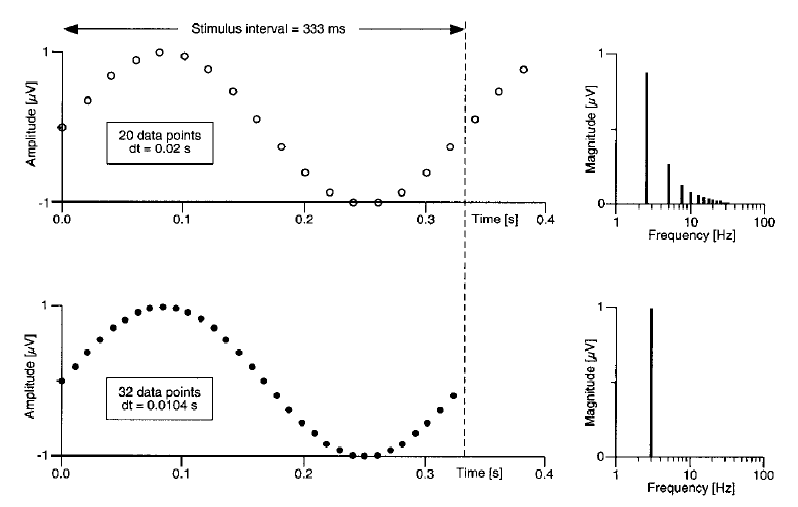

- the old sample rate, 

- a selection flag for the content of any files written to disk. for convenience, many of the indices calculated by the function are writte to disk

- and a name for the output file that is generated by the function. This output file will save to disk a structure array with the three main outputs of the function: the trial-wise amplitude at the frequency of interest, a measure of phase stability (within trial phase locking) at the frequency of interest, and the sliding window averages in the time domain for each trial (3-D array; electrodes by time ponts by trials).

[trialamp5Hz,winmat3d5Hz,phasestabmat5Hz,trialSNR5Hz] = freqtag_slidewin(exampledata_2, 0, 1:2500, 1:2500, 5, 500, 500, 'tag5Hz');

For the 6 Hz, we upsample to 600 Hz, to represent full cycles of the 6 Hz oscillation (166.667 ms) by an integer number of sample points:

[trialamp6Hz,winmat3d6Hz,phasestabmat6Hz,trialSNR6Hz] = freqtag_slidewin(exampledata_2, 0, 1:2500, 1:2500, 6, 600, 500, 'tag6Hz');

## 5-Examining and using the outputsfreqtag_slidewin

As noted above, the plotting flag can be used to illustrate the sliding window process and check the quality of the single-trial data. The plots generated display each subsequent sliding window in the top panel, with each line representing one sensor. The bottom panel shows how the sliding windows are continuously summed, and--if present in the signal-- four cycles of the time locked oscillation emerge. 

[dummy] = freqtag_slidewin(exampledata_2(:, :, 10), 1, 1:2500, 1:2500, 5, 500, 500, 'delete');

Above we plot only the 5 Hz response during the 10th trial, but readers may wish to examine all trials by uncommenting the next line: 

 % [dummy] = freqtag_slidewin(exampledata_2, 1, 1:2500, 1:2500, 5, 500, 500, 'delete');

As another quality check, it is useful to examine the internal consistency of the single trial indices. If the estimated indices (amplitude, phase-stability, SNR) are internally consistent, then the ranking of participants on these indices is expected to be stable across single trials. At the level of individual participants, one intuitive test of internal consistency is to examine the stability of the topography across single trials. Noisy estimates are expected to have low internal consistency (e.g., Cronbach's alpha) when using electrode locations as observations and trials as variables. Using freqtag_cronbach, we can apply this latter principle on the estimates obtained form the single trials. 

Finally, researchers may wish to combine the single trial estimates into a more robust estimate of evoked ssVEP power, by averaging across the moving windows obtained in all trials. This is accomplished by averaging across the third dimension (trials) of the winmat3d variable, for example: 

 meanwinmat = mean(winmat3d6Hz, 3);
 figure, 
 plot(meanwinmat'), title('Mean of moving windows at 6 Hz')
 xlabel ('Sample points (upsampled to 600 Hz)')
 ylabel ('Voltage')

Now, we project this short time series into the frequency domain and plot the data: 

% Note the sample rate is 600 Hz 
[amp, phase, freqs, fftcomp] = freqtag_FFT(meanwinmat, 600); 
figure,
bar(freqs(2:25), amp(75,2:25)');%75 is the Oz sensor
title('Spectrum of the mean window shifted at 6 Hz')
xlabel('Frequency (Hz)')

We repeat these same steps for the 5 Hz driving stimulus

meanwinmat = mean(winmat3d5Hz, 3); 
figure, 
plot(meanwinmat'); title('Mean of moving windows at 5 Hz')
xlabel ('Sample points (500 Hz)')
ylabel ('Voltage')
[amp, phase, freqs, fftcomp] = freqtag_FFT(meanwinmat, 500);
figure,
bar(freqs(2:25), amp(75,2:25)');%75 is the Oz sensor
title('Spectrum of the mean window shifted at 5 Hz')
xlabel('Frequency (Hz)')

The driving frequency and harmonics are clearly visible. 

Note that the two mean sliding window averages have different numers of sample points (time points) reflective of the different duration of 4 cycles at these two frequencies. 

We can now determine a simple signal-to-noise measure as used in the example 1, dividing amplitude at the driving frequency by the mean of suitabe bins without energy at the driving frequency or its harmonics. Opening (double clicking) the freqs vector for each frequency is a convenient way of determining these bins. 

meanwinmat = mean(winmat3d6Hz, 3);
[amp, phase, freqs, fftcomp] = freqtag_FFT(meanwinmat, 600);
[SNRdb6Hz, SNRratio6Hz] = freqtag_simpleSNR(amp, [4 6 8]);
bar(freqs(2:12), SNRdb6Hz(75, 2:12)'); %75 is the Oz sensor
title('SNR spectrum of the mean window shifted at 6 Hz')
xlabel('Frequency (Hz)')
ylabel('SNR in dB')

and again for the 5 Hz SSVEP

meanwinmat = mean(winmat3d5Hz, 3);
[amp, phase, freqs, fftcomp] = freqtag_FFT(meanwinmat, 500);
[SNRdb5Hz, SNRratio5Hz] = freqtag_simpleSNR(amp, [4 6 8]);
bar(freqs(2:12), SNRdb5Hz(75, 2:12)');%75 is the Oz sensor
title('SNR spectrum of the mean window shifted at 5 Hz')
xlabel('Frequency (Hz)')
ylabel('SNR in dB')

## 11-Close all figures and clean the worskpace

close all
clear all